clc; 
clear all; close all;
start=1;
x0 = [start;0]; % x0 is the intial state of the system

tspan=[0; 10]; % simulation time
global alpha;


record=zeros(0,2);
for alpha=3:0.001:5
    [t,x] = ode45(@sys_dynamics,tspan,x0);
    n=size(t,1);
    line0=zeros(n,1);
    SettlingTime=0;
    for i=1:n
        if abs(x(i,1))>start*0.05
            SettlingTime=t(i);
        end
    end
    record=[record;alpha,SettlingTime];
    if SettlingTime<=1
        break;
    end
end
alpha

alpha = 4.0650

SettlingTime

SettlingTime = 0.9795

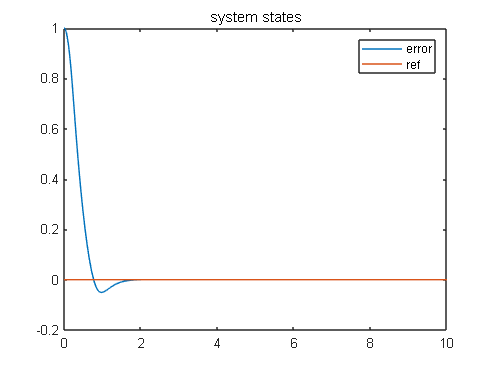

% overshoot=abs(overshoot/start*100)
 % plot the simulation data
figure; plot(t,x(:,1),t,line0); legend('error','ref'); title('system states');

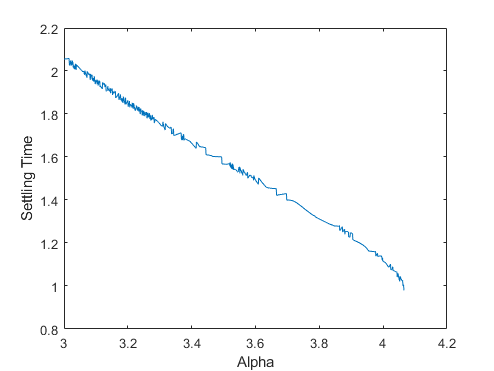

figure(2); plot(record(:,1),record(:,2)); xlabel('Alpha');ylabel('Settling Time'); 

function dx=sys_dynamics(t,x)
kp=30;
dx=zeros(2,1);
dx(1)=x(2);
dx(2)=-10*x(2)-kp*x(1);
dx(2)=constrain(dx(2));

end


function output=constrain(input)
global alpha;
output=input;
if(input<-9.81)
    output=-9.81;
elseif(input>(alpha-1))
    output=alpha-1;
end
end